label_dir = './watermelon-imgs/';
label_post = '_mask.tiff';
pred_dir = './tiff_files/';
pred_post = '_detected_mask.tiff';

N_pic = 31;
% Accuracy, Precision, Recall, 
% F1score, Specificity, IoU
all_metrics = zeros(N_pic, 6);
all_label = [];
all_pred = [];
for melon_idx = 1:N_pic
    file_name = strcat('melon', int2str(melon_idx), '.jpeg');
    
    label = imread(strcat(label_dir, file_name, label_post));
    pred = imread(strcat(pred_dir, file_name, pred_post));
    
    % figure;
    % montage([label, pred]);
    conf_mat = confusionmat(1-reshape(label,[],1), reshape(1-pred,[],1));
    metrics = class_metrics(conf_mat);
    all_metrics(melon_idx, :) = metrics;
    
    % TPE = recall, FPR = 1 - TNR = 1 - specficity
%     n = 2
%     label = mean(reshape(label,n,[]));
%     pred = mean(reshape(pred,n,[]));
%     averagingFunction = @(x) mean(x.data(:));
%     label = blockproc(label, [20, 20] , averagingFunction);
%     pred = blockproc(pred, [20, 20] , averagingFunction);
    
    all_label = [all_label; reshape(label,[],1)];
    all_pred = [all_pred; reshape(pred,[],1)];
    
end
all_metrics(isnan(all_metrics)) = 0;
all_FPR = 1 - all_metrics(:, 5);
all_TPR = all_metrics(:, 3);

% drop Accuracy Specificity
metrics = ["Accuracy" "Precision" "Recall" ...
    "F1score" "Specificity" "IoU"];
% metrics = metrics([2, 3, 4, 6]);
% all_metrics = all_metrics(:, [2, 3, 4, 6]);

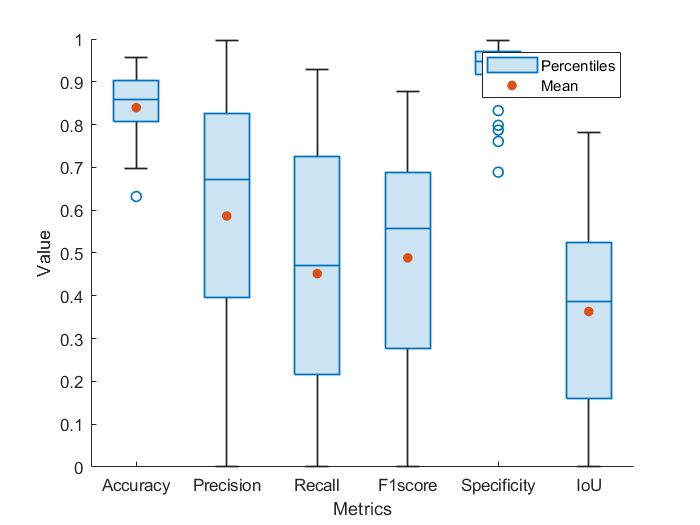


figure;
hold on;
boxchart(all_metrics);
plot(mean(all_metrics, 1), '.', 'MarkerSize', 20);
set(gca, 'XTickLabel', metrics);
xlabel("Metrics")
ylabel("Value")
legend('Percentiles', 'Mean', "Location", "northeast")
hold off;

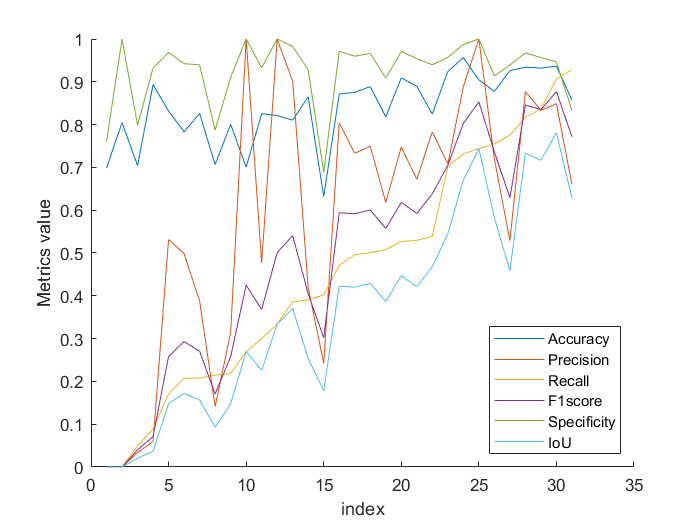

sorted_matrics = sort(all_metrics);
[~,I] = sort(all_metrics(:, 3));
% [~,I] = sort(mean(all_metrics, 2));
sorted_matrics_IoU = all_metrics(I, :);
figure;
hold on;
plot(sorted_matrics_IoU);
legend(metrics, "Location", "southeast");
xlabel("index")
ylabel('Metrics value')
hold off;

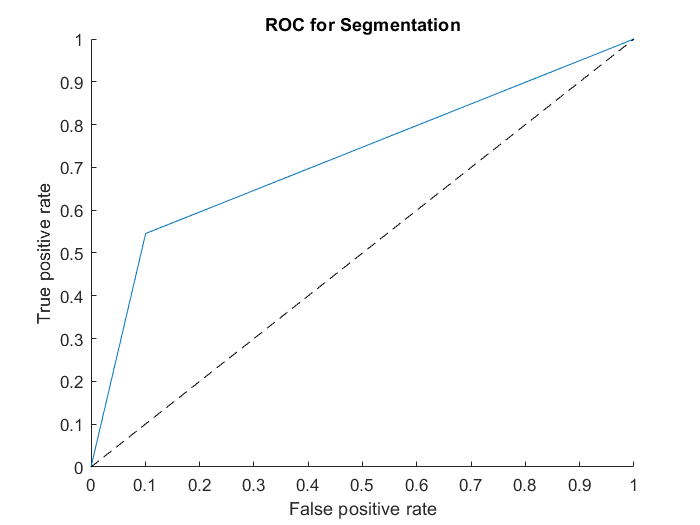

[X,Y,T,AUC] = perfcurve(all_label, all_pred, 1);
figure;
hold on;
plot(X,Y)
plot([0 1], [0 1], '--', 'Color', 'k')
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Segmentation')
hold off;

AUC

AUC = 0.7224